箭头绘制（arrowPlot&arrowPlotn）

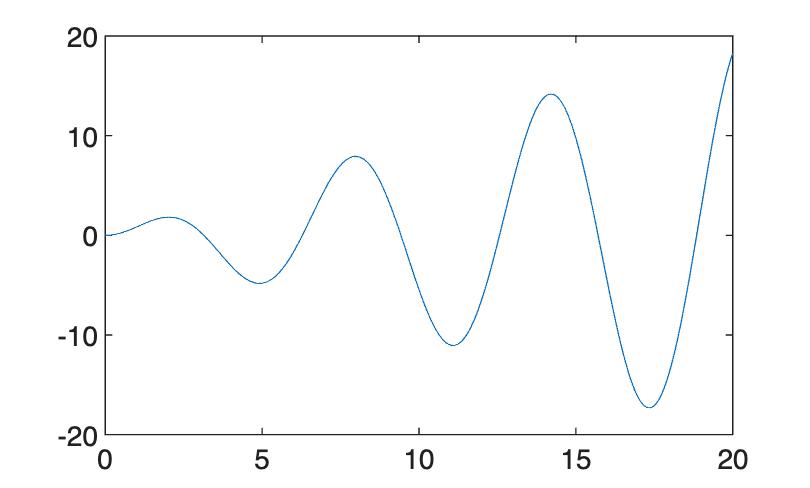

x = 0:0.01:20;
y = x.*sin(x);
plot(x,y);

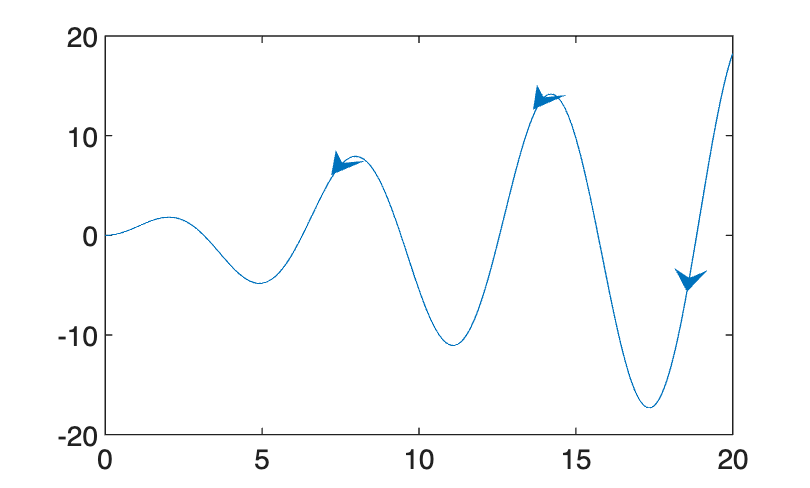

figure
arrowPlotn(x,y,'number',3);

点电荷的电场绘制(+)

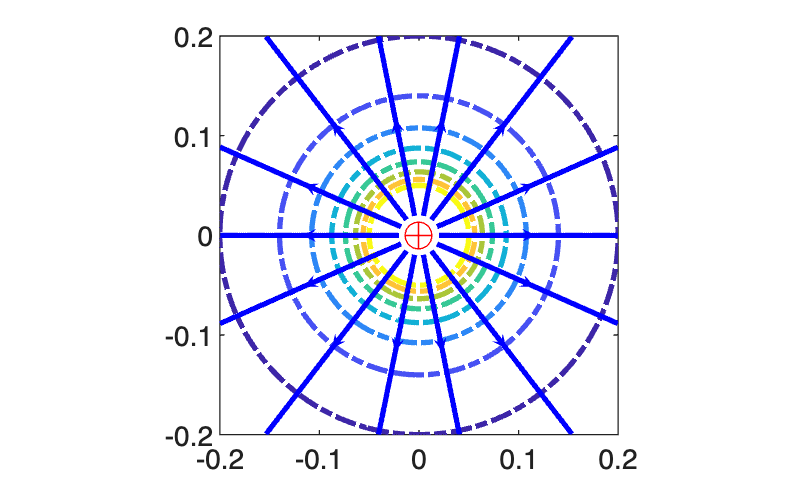

k = 8.9875e9;
e = 1.602e-19;
r1 = 0.2;
r0 = 0.2;

% 第二步：画点电荷及其等位线
plot(0,0,'ro',0,0,'r+','MarkerSize',10); %画点电荷
hold on;
axis equal;
Np = 60; %空间区域内场点的个数
x = linspace(-r0,r0,Np); %建立 x 向量
y = linspace(-r0,r0,Np); %建立 y 向量
[X,Y] = meshgrid(x,y); %建立 X,Y 矩阵
r = sqrt(X.^2 + Y.^2); %场点与点电荷的距离
U = k * e ./ r; %场中任意一点的电势
u0 = k * e / r1; %基准电势
u = linspace(1,4,8) * u0; %选取需要画出的等位线
contour(X,Y,U,u,'-.','LineWidth',2); %画电势线

% 第三步：求点电荷的电场
hold on;
[Ex,Ey] = gradient(-U); %求电场强度的 X,Y 方向分量
E = sqrt(Ex.^2 + Ey.^2); %求电场强度
% 第四步：画点电荷的电力线
Ex = Ex ./ E;      % 归一化处理
Ey = Ey ./ E;      % 绘制的场线数量
Ne = 15;           % 建立 t 向量
t = linspace(0, 2 * pi, Ne);
rd = r0 * 0.1;     % 选择电场线起始的半径
start_x = rd * cos(t); % 选择电场线起点
start_y = rd * sin(t);
for i = 1:15
    h = streamline(X, Y, Ex, Ey, start_x(i), start_y(i)); %画电场线
    arrowPlot(h.XData, h.YData, 'number', 1, 'color', 'b', 'LineWidth', 2); %画箭头
    hold on;
end
hold off

负点电荷的电场绘制（-）

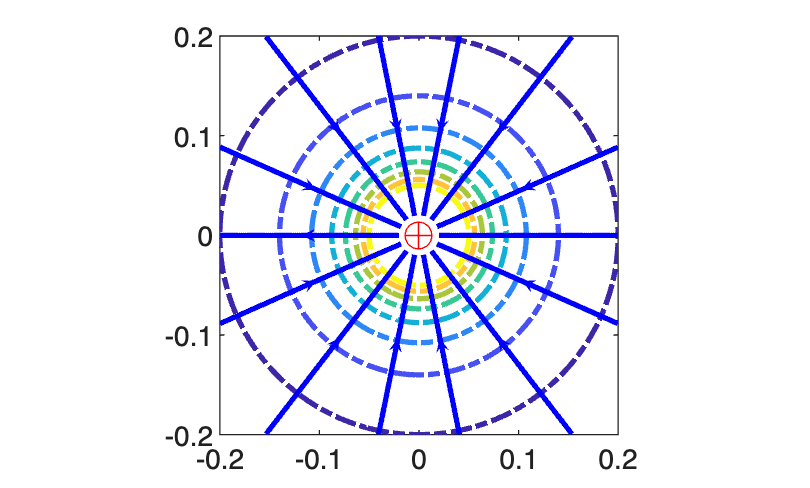

k = 8.9875e9;
e = 1.602e-19;
r1 = 0.2;
r0 = 0.2;

% 第二步：画点电荷及其等位线
plot(0,0,'ro',0,0,'r+','MarkerSize',10); %画点电荷
hold on;
axis equal;
Np = 60; %空间区域内场点的个数
x = linspace(-r0,r0,Np); %建立 x 向量
y = linspace(-r0,r0,Np); %建立 y 向量
[X,Y] = meshgrid(x,y); %建立 X,Y 矩阵
r = sqrt(X.^2 + Y.^2); %场点与点电荷的距离
U = k * e ./ r; %场中任意一点的电势
u0 = k * e / r1; %基准电势
u = linspace(1,4,8) * u0; %选取需要画出的等位线
contour(X,Y,U,u,'-.','LineWidth',2); %画电势线

% 第三步：求点电荷的电场
hold on;
[Ex,Ey] = gradient(-U); %求电场强度的 X,Y 方向分量
E = sqrt(Ex.^2 + Ey.^2); %求电场强度
% 第四步：画点电荷的电力线
Ex = Ex ./ E;      % 归一化处理
Ey = Ey ./ E;      % 绘制的场线数量
Ne = 15;           % 建立 t 向量
t = linspace(0, 2 * pi, Ne);
rd = r0 * 0.1;     % 选择电场线起始的半径
start_x = rd * cos(t); % 选择电场线起点
start_y = rd * sin(t);
for i = 1:15
    h = streamline(X, Y, Ex, Ey, start_x(i), start_y(i)); %画电场线
    arrowPlotn(h.XData, h.YData, 'number', 1, 'color', 'b', 'LineWidth', 2); %画箭头
    hold on;
end
hold off

电偶极子的电场

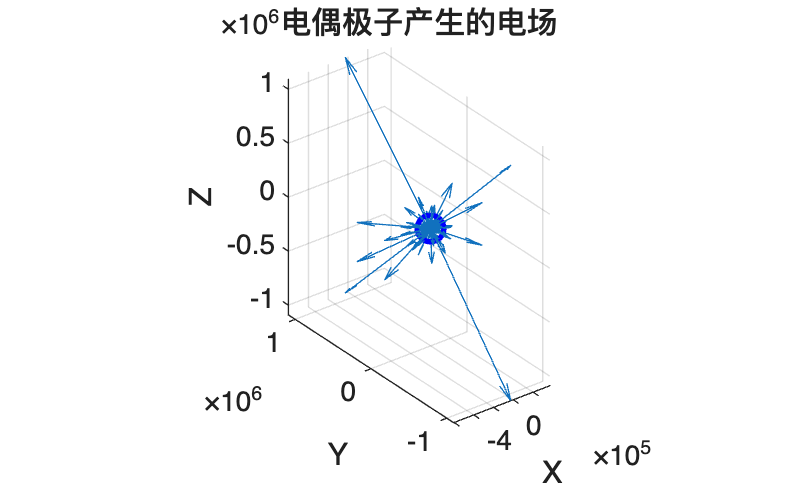

% 参数设置
k = 8.9875e9; % 库仑常数
q = 1e-9; % 电荷量，单位库仑
d = 0.01; % 偶极矩大小，单位米
r1 = 0.1; % 绘制范围的半径
r0 = d / 2; % 偶极子中心到电荷的距离

% 空间网格
Np = 60; % 空间区域内场点的个数
x = linspace(-r1, r1, Np);
y = linspace(-r1, r1, Np);
z = linspace(-r1, r1, Np);
[X, Y, Z] = meshgrid(x, y, z);

% 计算每个点到正电荷和负电荷的距离
r1 = sqrt((X - r0).^2 + Y.^2 + Z.^2);
r2 = sqrt((X + r0).^2 + Y.^2 + Z.^2);

% 计算电场分量
Ex = (k * q / r1.^3) .* (X - r0) - (k * q / r2.^3) .* (X + r0);
Ey = (k * q / r1.^3) .* Y - (k * q / r2.^3) .* Y;
Ez = (k * q / r1.^3) .* Z - (k * q / r2.^3) .* Z;

% 绘制电场线
figure;
quiver3(X, Y, Z, Ex, Ey, Ez, 'AutoScale', 'off');
hold on;
plot3([r0, r0], [0, 0], [0, 0], 'ro', 'MarkerSize', 10, 'LineWidth', 2); % 绘制正电荷
plot3([-r0, -r0], [0, 0], [0, 0], 'bo', 'MarkerSize', 10, 'LineWidth', 2); % 绘制负电荷
xlabel('X');
ylabel('Y');
zlabel('Z');
title('电偶极子产生的电场');
axis equal;
grid on;
view(3);